clc;
clear;
close all;

%% Pressure Process Model Parameters
K = 2;          % Process gain
tau = 5;        % Time constant

num = [K];
den = [tau 1];

plant = tf(num,den);

disp('Pressure Process Transfer Function:')

Pressure Process Transfer Function:


plant


plant =
 
     2
  -------
  5 s + 1
 
Continuous-time transfer function.


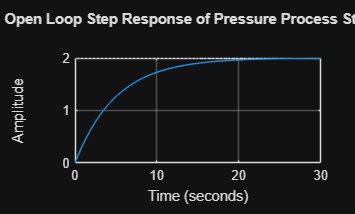


%% Step Response of Open Loop System
figure;
step(plant)
grid on
title('Open Loop Step Response of Pressure Process Station')

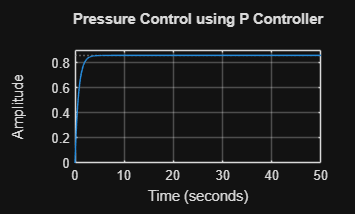


%% Time vector
t = 0:0.01:50;

%% P Controller
Kp = 3;

C_p = pid(Kp);

sys_p = feedback(C_p*plant,1);

figure;
step(sys_p,t)
title('Pressure Control using P Controller')
grid on

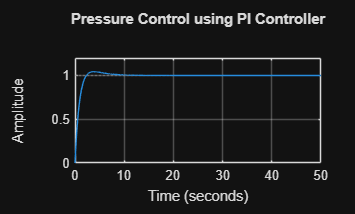


%% PI Controller
Kp = 3;
Ki = 1;

C_pi = pid(Kp,Ki);

sys_pi = feedback(C_pi*plant,1);

figure;
step(sys_pi,t)
title('Pressure Control using PI Controller')
grid on

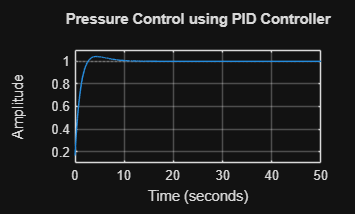


%% PID Controller
Kp = 3;
Ki = 1;
Kd = 0.5;

C_pid = pid(Kp,Ki,Kd);

sys_pid = feedback(C_pid*plant,1);

figure;
step(sys_pid,t)
title('Pressure Control using PID Controller')
grid on

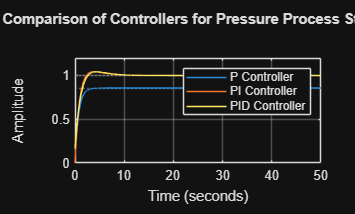


%% Compare All Controllers
figure;
step(sys_p,sys_pi,sys_pid,t)
legend('P Controller','PI Controller','PID Controller')
title('Comparison of Controllers for Pressure Process Station')
grid on